load cassiniData2.mat

Year = data(:,1);
Month = data(:,2);
Day = data(:,3);
X = data(:,4);
Y = data(:,5);
Z = data(:,6);



Planets = {'Mercury','Venus','Earth','Mars',...
    'Jupiter','Saturn','Uranus','Neptune'};
OrbitRad = [0.39,0.72,1,1.51,5.0,9.04,19.18,30.06];


Radial = sqrt(X.^2 + Y.^2 + Z.^2);

vidx = 0.01 >= abs(Radial - OrbitRad(2))

vidx =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   1
   1
   1
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   1
   1
   0
   1
   1
   0
   0
   0
   


D = Radial - OrbitRad(2)

D =     0.2800
    0.2800
    0.2800
    0.2800
    0.2800
    0.2800
    0.2800
    0.2900
    0.2900
    0.2900

S = sign(D)

S =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1

C = diff(S)

C =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0

idx = C ~= 0

idx =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



vidx = Radial == OrbitRad(2);
nnz(vidx)

ans = 7

Planets(2)

ans =     'Venus'

vTime = [Year(vidx),Month(vidx),Day(vidx)]

vTime =         1998           2          27
        1998           2          28
        1999           6          25
        1999           6          26
        1999           6          27
        1999           6          28
        1999           7           2


midx = Radial == OrbitRad(1);
nnz(midx)

ans = 0

Planets(1)

ans =     'Mercury'

mTime = [Year(midx),Month(midx),Day(midx)]

mTime =
  0×3 empty double matrix



midx = Radial == OrbitRad(3);
nnz(midx)

ans = 15

Planets(3)

ans =     'Earth'

mTime = [Year(midx),Month(midx),Day(midx)]

mTime =         1997          10          17
        1997          10          18
        1997          10          19
        1997          10          20
        1997          10          21
        1997          11          21
        1997          11          22
        1997          11          23
        1997          11          24
        1997          11          26


midx = Radial == OrbitRad(4);
nnz(midx)

ans = 3

Planets(4)

ans =     'Mars'

mTime = [Year(midx),Month(midx),Day(midx)]

mTime =         1998          10          14
        1998          10          15
        1999           1          29


midx = Radial == OrbitRad(5);
nnz(midx)

ans = 2

Planets(5)

ans =     'Jupiter'

mTime = [Year(midx),Month(midx),Day(midx)]

mTime =         2000          12          28
        2000          12          29


midx = Radial == OrbitRad(6);
nnz(midx)

ans = 2

Planets(6)

ans =     'Saturn'

mTime = [Year(midx),Month(midx),Day(midx)]

mTime =         2004           6          30
        2004           7           1

min(Year)

ans = 1997

max(Year)

ans = 2004

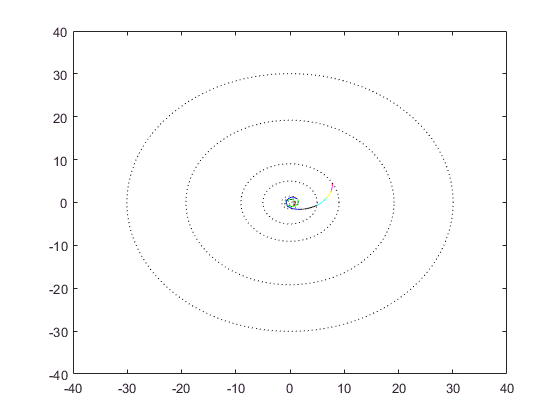


idx = Year == 1997;
plot(X(idx),Y(idx),'r')

hold on

idx = Year == 1998;
plot(X(idx),Y(idx),'g')

idx = Year == 1999;
plot(X(idx),Y(idx),'b')

idx = Year == 2000;
plot(X(idx),Y(idx),'k')

idx = Year == 2001;
plot(X(idx),Y(idx),'c')

idx = Year == 2002;
plot(X(idx),Y(idx),'y')

idx = Year == 2003;
plot(X(idx),Y(idx),'m')

idx = Year == 2004;
plot(X(idx),Y(idx),'r')


ang = linspace(0,2*pi,1000);
xp = OrbitRad.*cos(ang');
yp = OrbitRad.*sin(ang');

plot(xp,yp,'k:')




hold off